# **Lab 2**

# Problem 1

In lecture and homework we explored how the convolution can be used to calculate the probability of a sum or average. For this problem we are going to imagine that we are looking for gamma-ray sources (e.g. with the [Fermi telescope](https://fermi.gsfc.nasa.gov)). In this kind of telescope there is a background of cosmic-rays (electrons and protons, mostly) that provides a discrete noise term across the sky that precisely follows a Poisson distribution. To detect a gamma-ray source, you need to ask what is the probability that the cosmic-ray background would have given you a measurement as signal-like or more than the signal that you received.

To set up the problem, assume in 1 day the average cosmic-ray background is some number X (pick someting btwn 0.5 and 10, with different values for you and your lab partner); and the average number of gamma-rays emitted by your hypothetical source is Y (pick something larger than X).

A) Show how the probability distribution of the background changes as you integrate (sum) for more days.

 - convolve random distribution with itself, show how distribution evolves with more convolutions

- compare convolved with a poisson of a different parameter. 

X = 2.6;

X = 2.6000

Y = 5.9;

Y = 8.5000

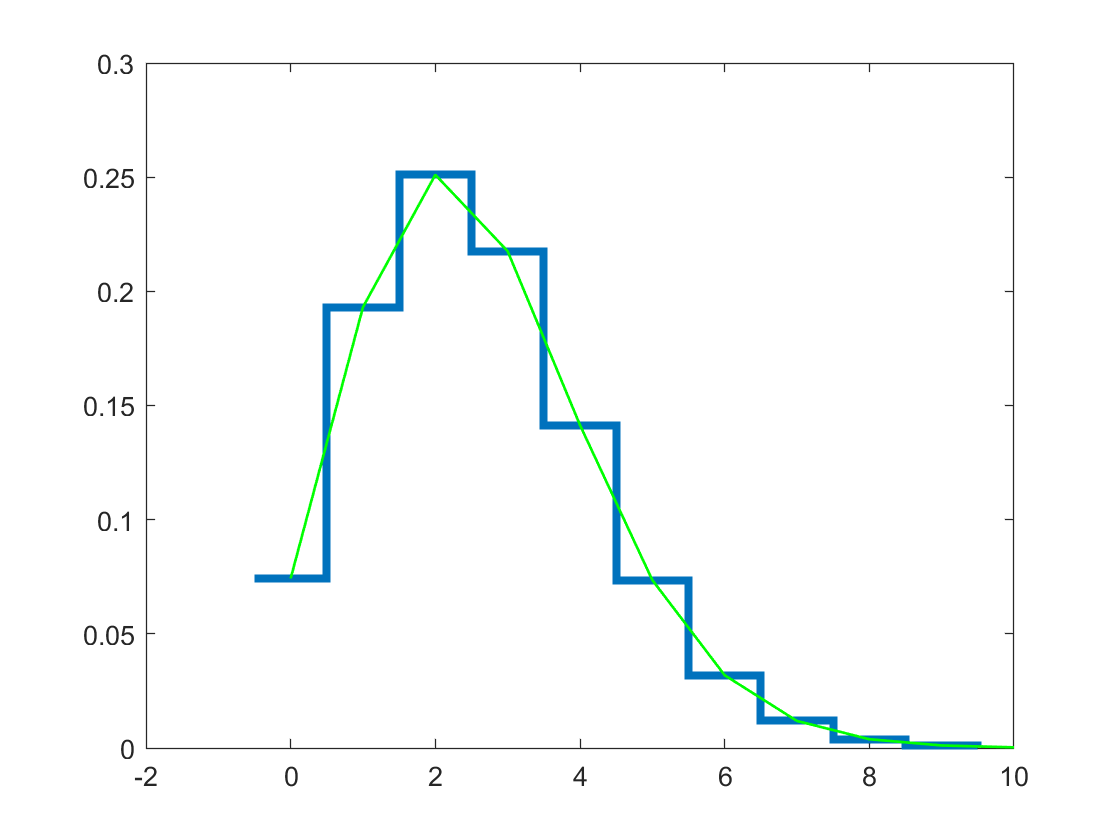


xvals = 0:10;
poisson = makedist("Poisson","lambda",X);

stairs(xvals-0.5,pdf(poisson,xvals),"LineWidth",3)
hold on
plot(xvals,pdf(poisson,xvals),"LineWidth",1,"Color","green")
hold off

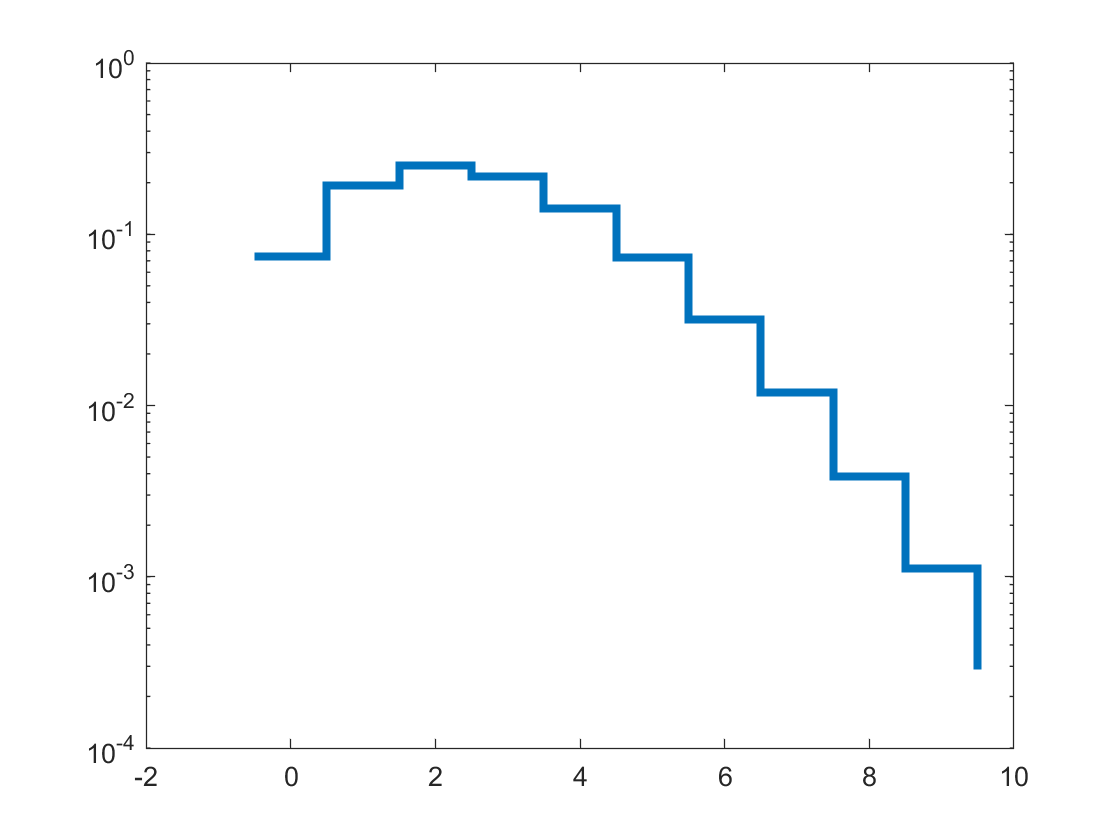


stairs(xvals-0.5,pdf(poisson,xvals),"LineWidth",3)
set(gca,'YScale','log')

B) Show that after 5 days, the summed probability distribution is still a Poisson distribution. Explain why this makes sense from a mathematical and conceptual point of view. 

C) Show how the probability distribution evolves as you *average* days. Calculate for many different ranges of days, and explore the shape of the distribution as the number of days becomes larger. Discuss this in relation to both B) and the central limit theoem.

D) Pick some number of days N, and assume you saw Y*N gamma rays from your source. Calculate the 'sigma' of your observation. [In reality the number of gamma-rays seen from a source will also fluctuate, but we're going to ignore that complication for a couple of labs.]